mo% Example on Hopkins155 dataset
% Data obtained from: http://www.vision.jhu.edu/data/hopkins155/

## Load Hopkins data

%subsample frames to simulate high-rank setting
load data/hopkins_1R2RC_truth.mat
disp(x)


(:,:,1) =

    0.3469    0.3406    0.2125   -0.2625    0.2781    0.3000    0.2688   -0.6250    0.3844    0.2250    0.3125   -0.6406   -0.7281    0.2531    0.3375    0.2594   -0.6469   -0.7688    0.4344    0.4375   -0.6281   -0.7781    0.5000   -0.6844   -0.7188    0.3781    0.4031   -0.6813    0.2594   -0.6250   -0.6844   -0.7531    0.5594   -0.7500   -0.1250    0.2906   -0.6813    0.5000    0.3187    0.3469   -0.0688    0.2562    0.5375    0.4531   -0.4000    0.5219   -0.2531   -0.7469   -0.7719    0.4469    0.4125    0.3938    0.3688   -0.6500   -0.1781   -0.0719   -0.1281    0.4344   -0.7219    0.5312    0.4500    0.2219    0.0563   -0.1969    0.6219    0.5750    0.4781   -0.0875    0.4094   -0.0688    0.3219    0.3125    0.4688    0.4906    0.3594    0.3563    0.3313    0.5250    0.4437    0.5031   -0.0406   -0.7219   -0.7281   -0.0969   -0.7906   -0.0563   -0.6687    0.5312   -0.2188   -0.0656    0.5625    0.3313   -0.0969    0.3281   -0.0344   -0.0344   -0.1063   -0.0500   -0.17

s = size(x,2); %num data points
F = 6;
frames = floor(linspace(1,size(x,3)-1,F)); %even spacing between frames
n = 2*F;
Xtrue = reshape(permute(x(1:2,:,frames),[1 3 2]),n,s);
disp("done")

done


## Subsample data uniformly at random

(in pairs of (x,y) coordinates)

rng(10); %fix random seed
missrate = 0.3;
sampmask_sm = false(F,s);
rind = randperm(F*s);
rv = round((1-missrate)*F*s);
sampmask_sm(rind(1:rv)) = true;
sampmask = false(n,s);
sampmask(1:2:(n-1),:) = sampmask_sm;
sampmask(2:2:n,:) = sampmask_sm;
samples = Xtrue(sampmask);
Xinit = zeros(n,s);
Xinit(sampmask) = samples;
disp("done")

done


## Run low-rank matrix completion (LRMC) for baseline

options_nn.lambda = 1e8;
options_nn.mu = 1;
options_nn.niter = 1000;
Xlrmc = lrmc_admm(Xinit,sampmask,samples,options_nn);
%Xlrmc = lrmc_cvx(sampmask,samples); % CVX version
fprintf('LRMC NRMSE = %1.2e\n',norm(Xlrmc-Xtrue,'fro')/norm(Xtrue,'fro'));

LRMC NRMSE = 1.07e-02


disp("done")

done


## Run variety-based matrix completion (VMC)

options = [];
options.d = 2; %kernel degree
options.c = 1; %use inhomogeneous kernel for affine union of subspaces model
options.niter = 3000;
[Xvmc,cost,update,error] = vmc(Xinit,sampmask,samples,options,Xtrue);

VMC set options.eigcomp='lift-svd' based on problem size
VMC reached exit tolerance at iter 2322


fprintf('VMC NRMSE = %1.2e\n',norm(Xvmc-Xtrue,'fro')/norm(Xtrue,'fro'));

VMC NRMSE = 1.43e-03


disp("done")

done


## Display columnwise errors

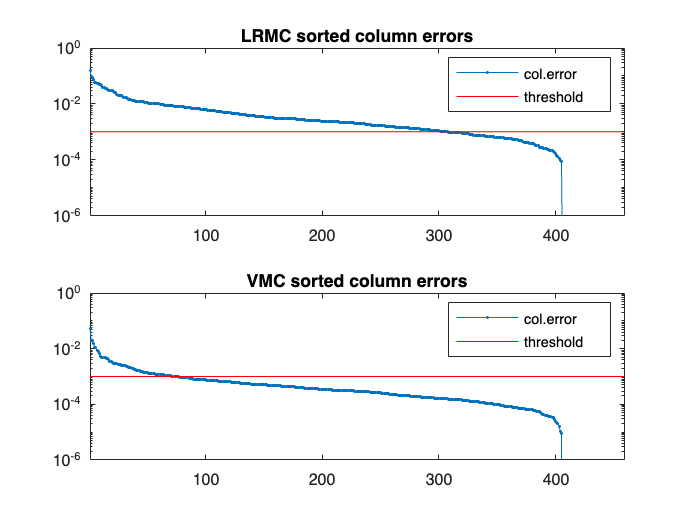

figure(1);
colerr_vmc = zeros(1,s);
colerr_lrmc = zeros(1,s);
for j = 1:s
    colerr_vmc(j) = norm(Xvmc(:,j)-Xtrue(:,j))/norm(Xtrue(:,j));
    colerr_lrmc(j) = norm(Xlrmc(:,j)-Xtrue(:,j))/norm(Xtrue(:,j));
end
[colerr_vmc,idx] = sort(colerr_vmc,'descend');
[colerr_lrmc,idx] = sort(colerr_lrmc,'descend');
errthresh = 1e-3;

subplot(2,1,1);
semilogy(colerr_lrmc,'.-'); title('LRMC sorted column errors');
hold on
line([0 s],[errthresh errthresh],'Color','red');
hold off
axis([1 s 1e-6 1]);
legend('col.error','threshold');
subplot(2,1,2);
semilogy(colerr_vmc,'.-'); title('VMC sorted column errors');
hold on
line([0 s],[errthresh errthresh],'Color','red');
hold off
legend('col.error','threshold');
axis([1 s 1e-6 1]);

fprintf('LRMC recovered %2.1f%% columns (%d of %d) with err < %1.1e\n',(nnz(colerr_lrmc < errthresh)/s)*100,nnz(colerr_lrmc < errthresh),s,errthresh);

LRMC recovered 33.3% columns (153 of 459) with err < 1.0e-03


fprintf('VMC recovered %2.1f%% columns (%d of %d) with err < %1.1e\n',(nnz(colerr_vmc < errthresh)/s)*100,nnz(colerr_vmc < errthresh),s,errthresh);

VMC recovered 84.7% columns (389 of 459) with err < 1.0e-03
